clock_freq = 400*10^(6);
clk_period = 1/clock_freq

clk_period = 2.5000e-09

clk_rate = clk_period/2

clk_rate = 1.2500e-09

pancham_cycles = 75;
num_passwords = 14776336;
num_supervisors = [1 , 2, 4, 8, 16, 32]

num_supervisors =      1     2     4     8    16    32


sec_per_hash = pancham_cycles*clk_period

sec_per_hash = 1.8750e-07

hash_per_nsec = 1/sec_per_hash*num_supervisors*10^(-9)

hash_per_nsec =     0.0053    0.0107    0.0213    0.0427    0.0853    0.1707


worst_case_time = sec_per_hash*num_passwords./num_supervisors

worst_case_time =     2.7706    1.3853    0.6926    0.3463    0.1732    0.0866


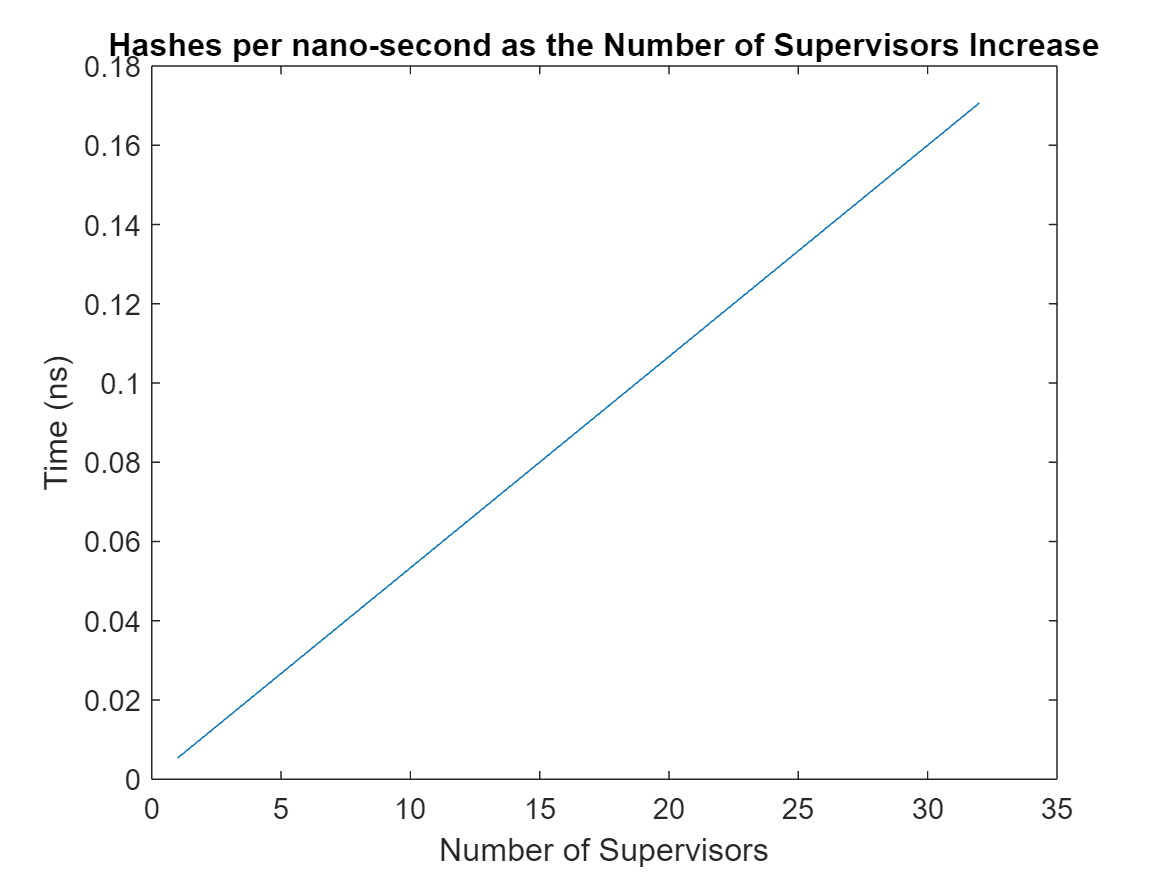

plot(num_supervisors, hash_per_nsec);
hold on
title 'Hashes per nano-second as the Number of Supervisors Increase'
hold off

xlabel("Number of Supervisors")
ylabel("Time (ns)")

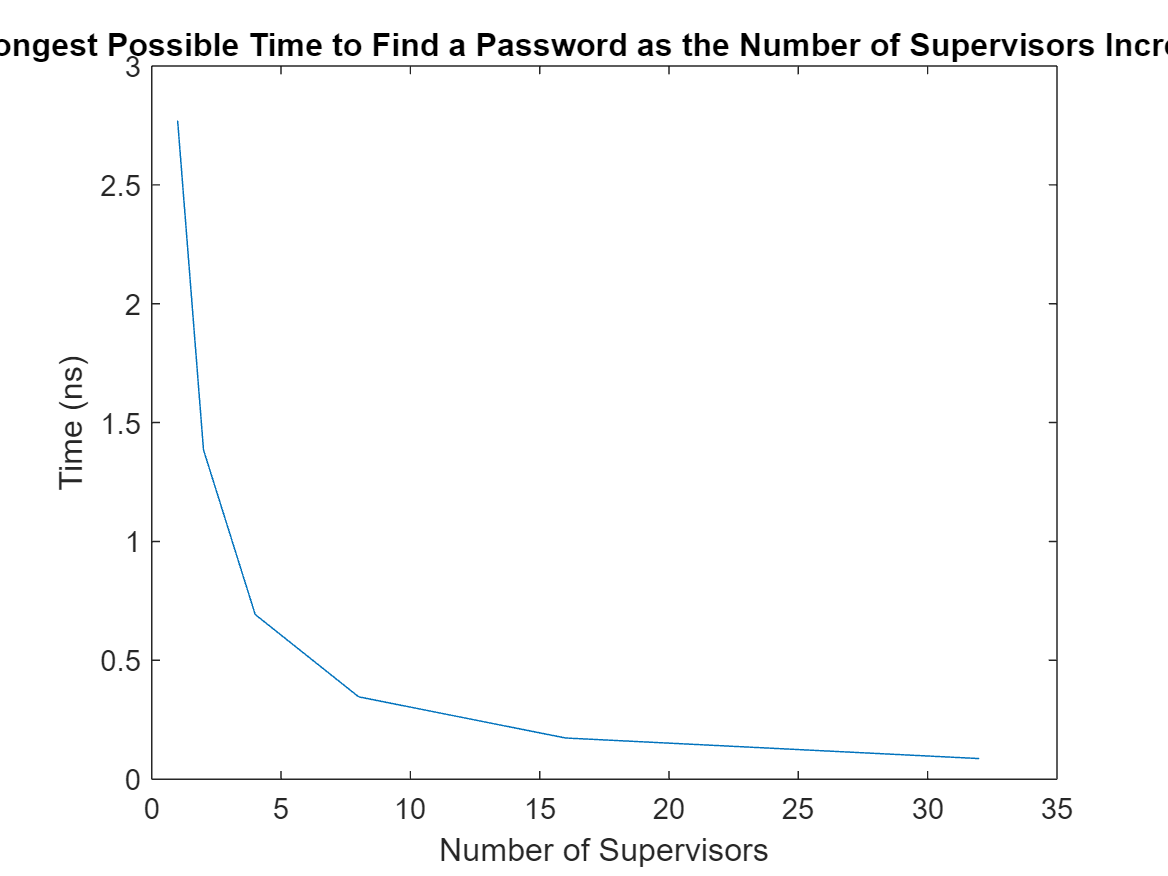


plot(num_supervisors,worst_case_time);
hold on
title 'Longest Possible Time to Find a Password as the Number of Supervisors Increase'
hold off

xlabel("Number of Supervisors")
ylabel("Time (ns)")